

R = 280; % Resistance in ohms
L = 2.0; % Inductance in henries
C = 8e-6; % Capacitance in farads
Vin_val = 30; % Input voltage in volts (constant)


Vc0 = 6; % Initial voltage across the capacitor in volts
Il0 = 0; % Initial current through the inductor in amperes

% Time vector for simulation
t_numeric = linspace(0, 0.1, 1000); % Simulate for 0.1 seconds with 1000 points

% Analytical solution for vL(t)
syms t
alpha = R / (2 * L); % Damping factor
omega0 = 1 / sqrt(L * C); % Resonant angular frequency
omega_d = sqrt(omega0^2 - alpha^2); % Damped angular frequency

% Define the voltage across the inductor vL(t)
vL_t = exp(-alpha * t) * (24 * cos(omega_d * t) + (-7) * sin(omega_d * t));

% Substitute symbolic solution into numeric time vector
vL_numeric = double(subs(vL_t, t, t_numeric));

% Calculate voltage across capacitor
vC_t = Vin_val - vL_t;
vC_numeric = double(subs(vC_t, t, t_numeric));

% Calculate total current in the circuit
i_t = (Vin_val - vC_numeric - vL_numeric) / R;

% Display alpha and omega values
fprintf('Alpha (α) = %.2f, Omega0 (ω_0) = %.2f, Omega_d (ω_d) = %.2f\n', alpha, omega0, omega_d);

Alpha (α) = 70.00, Omega0 (ω_0) = 250.00, Omega_d (ω_d) = 240.00


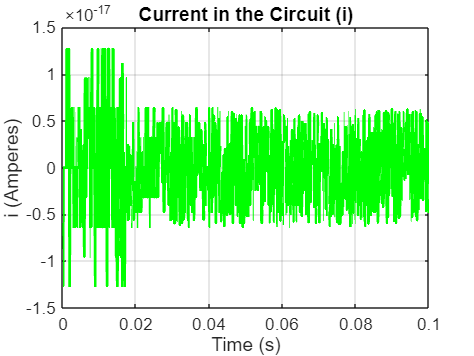


% User menu for selecting output
choice = menu('Select the output to display:', ...
    'Voltage across Inductor (vL)', ...
    'Voltage across Capacitor (vC)', ...
    'Current in the circuit (i)', ...
    'Voltage across Resistor (vR)');

% Generate the selected output
figure;
switch choice
    case 1 % Voltage across Inductor (vL)
        plot(t_numeric, vL_numeric, 'm', 'LineWidth', 1.5);
        title('Voltage across the Inductor (v_L)');
        ylabel('v_L (Volts)');
        equation_str = sprintf('$$v_L(t) = e^{-%.2ft}[%.2f\\cos(%.2ft) + %.2f\\sin(%.2ft)]$$', ...
            alpha, 24, omega_d, -7, omega_d);
        text(0.02, 15, equation_str, 'Interpreter', 'latex', 'FontSize', 12, 'Color', 'm');
        
    case 2 % Voltage across Capacitor (vC)
        plot(t_numeric, vC_numeric, 'b', 'LineWidth', 1.5);
        title('Voltage across the Capacitor (v_C)');
        ylabel('v_C (Volts)');
        
    case 3 % Current in the circuit (i)
        plot(t_numeric, i_t, 'g', 'LineWidth', 1.5);
        title('Current in the Circuit (i)');
        ylabel('i (Amperes)');
        
    case 4 % Voltage across Resistor (vR)
        vR_numeric = R * i_t;
        plot(t_numeric, vR_numeric, 'r', 'LineWidth', 1.5);
        title('Voltage across the Resistor (v_R)');
        ylabel('v_R (Volts)');
        
    otherwise
        disp('No selection made. Exiting...');
        return;
end

xlabel('Time (s)');
grid on;